NCC_st.name='NCC'; 
NCC_st.lat=38.9;
NCC_st.lon=-77.04;
NCC_st.alt=514;
NCC_st.env='con';
NCC_st.footp='U';


NCC_rd=read_betsy('NCC_head',NCC_st.name);

datevec(NCC_rd.Time(1))

ans =         2003           4           2           0           0           0

datevec(NCC_rd.Time(end))

ans =         2016           4           1           0           0           0

prctile(NCC_rd.U_S,[5 50 95])

ans =    38.4690   62.7250   90.2978

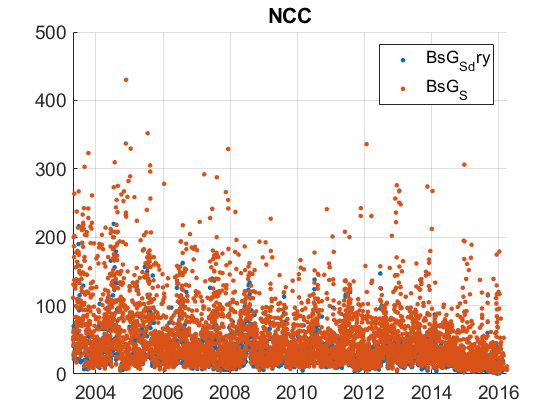

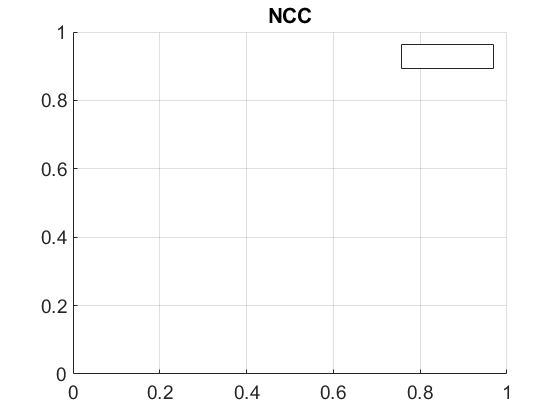

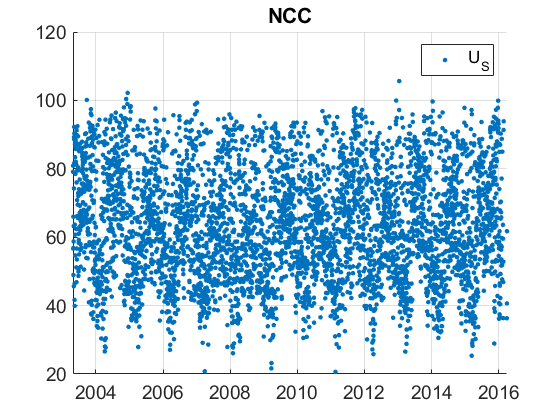

plotFigControl(NCC_rd,NCC_st.name);

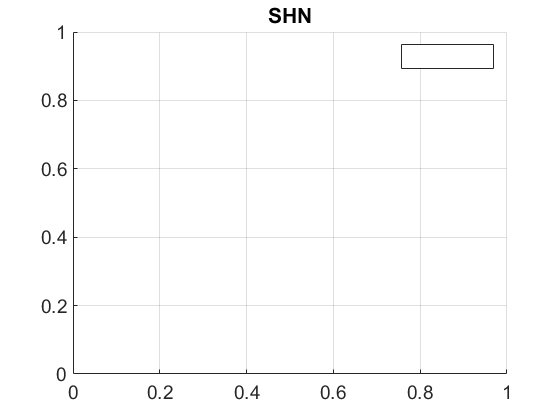

% 1 size cut, TSP
% sc: ok, max not so well defined, no negatives
% dry --> a lot of small holes
% % lambdaSC=[450;550;700]*ones(1,4);% % lambdaAE=[467;530;660]*ones(1,4);% % %lambdaAE7=[370 470 520 590 660 880 950];% % NCC_cal=compute_exp_SSA(NCC_rd,lambdaSC, lambdaAE);% % plotFigControl_cal(NCC_cal, NCC_st.name);

%Questions:
%problems: no seems to be OK
% clearly decreasing from 2014 to 2016. Any instrumental reason ?

NCC_tr=NCC_rd;
NCC_tr.y=year(NCC_tr.Time);

% begin at the beginning of a year: 2004
%end 2015
P=timerange('2004-01-01','2016-01-01');
NCC_tr=NCC_tr(P,:);

names=fieldnames(NCC_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    NCC_tr.(N{i})=[];
end

% dry: a lot of missing in winter

NCC_result= all_trend_STN(NCC_tr,NCC_st); 


NCC_result_D=NCC_result;

